# Shifting water depths

This guide explains how to shift all water depths in a bathymetry

## About

Shifting all water depths up or down can be a useful procedure. For example, this might be useful in order to deepen the entire domain by, say, 1 m in order to ensure that cages do not intesect the seabed. Alternatively, smoothing the data can sometimes result in a slight shallowing of the water depths, and therefore a slight deepening might be useful in conjunctions with a smoothing operation. Obviously, any deepending or shallowing of the domain should be applied sensiible and final bathymetry data compared with raw data.

## Initialise original bathymetry data

We start with an original bathymetry representation

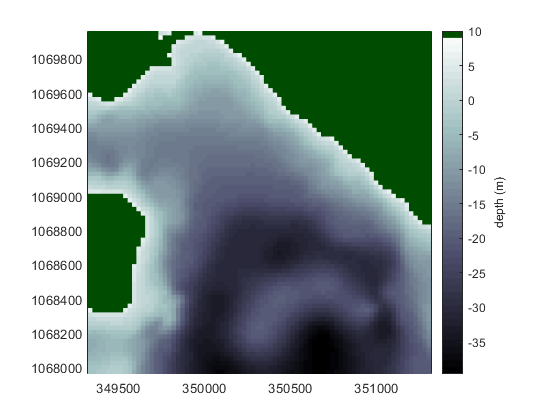

projectDir = 'C:\newdepomod_projects\bay_of_fish';
project    = Depomod.Project.create(projectDir);
bathy      = project.bathymetry;

bathy.plot

## Shift all water depths

Now, let's - just for the purpose of illustration - deepen the entire domain by 50 m.

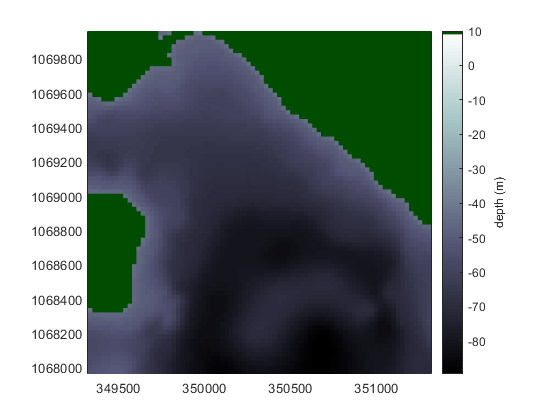

bathy.adjustSeabedDepths(50)

bathy.plot

And equally, we can shallow the domain by using a negative argument

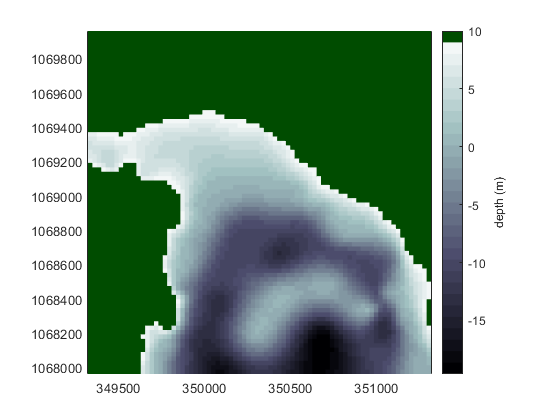

bathy.adjustSeabedDepths(-70)

bathy.plot

This last example isn't ideal. We've completely changed the coastline. Lets say we only want to shallow the deepest water depths in the original bathymetry. How can we do that?

## Manually altering water depths

First, let's revert back to the original

projectDir = 'C:\newdepomod_projects\bay_of_fish';
project    = Depomod.Project.create(projectDir);
bathy      = project.bathymetry;

Now, we want to find only the water depths that are, say, deeper than 15 m.

indxs = bathy.data < -15

indxs = 79×79 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

This is a boolean matrix representing true or false for every domain cell. We can use these indexes to set only the cells which are deeper than 15 m to 15 m.

bathy.data(indxs) = -15;

And plot to check the results

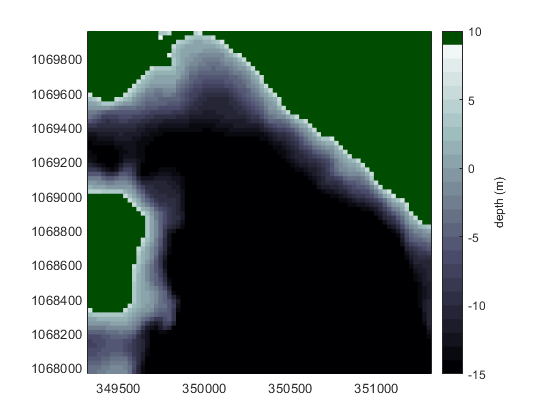

bathy.plot

That did the trick. The domain has been significantly shallowed, but without destroying the coastline in the process. 

This example is intended to convey the process by which the water depth data can be manually edited.

## Saving new data

In order to commit the changes to file, Matlab must be explicitly instructed to do so.

bathy.toFile